# Cholesky Decomposition Correlated Five Dimensional Multivariate Normal Shock

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

Generate variance-covariance matrix from correlation and standard deviation. Draw five correlated normal shocks using the MVNRND function. Draw five correlated normal shocks from uniform random variables using Cholesky Decomposition.

- [fs_cholesky_decomposition](https://fanwangecon.github.io/M4Econ/simulation/normal/htmlpdfm/fs_cholesky_decomposition.html)

- [fs_cholesky_decomposition_d5](https://fanwangecon.github.io/M4Econ/simulation/normal/htmlpdfm/fs_cholesky_decomposition_d5.html)

- [fs_bivariate_normal](https://fanwangecon.github.io/M4Econ/simulation/normal/htmlpdfm/fs_bivariate_normal.html)

## Correlation and Standard Deviations to Variance Covariance Matrix

Given correlations and standard deviations, what is the variance and covariance matrix? Assume mean 0. The first three variables are correlated, the final two are iid. 

First the ingredients:

% mean array
ar_mu = [0,0,0,0,0];
% standard deviations
ar_sd = [0.3301, 0.3329, 0.3308, 2312, 13394];
% correlations 
mt_cor = ...
    [1,0.1226,0.0182,0,0;...
     0.1226,1,0.4727,0,0;...
     0.0182,0.4727,1,0,0;...
     0,0,0,1,0;...
     0,0,0,0,1];
% show
disp(mt_cor);

    1.0000    0.1226    0.0182         0         0
    0.1226    1.0000    0.4727         0         0
    0.0182    0.4727    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000



Second, we know that variance is the square of standard deviation. And we know the formula for covariance, which is variance divided by two standard deviations. So for the example here, we have:

% initialize
mt_varcov = zeros([5,5]);
% variance
mt_varcov(eye(5)==1) = ar_sd.^2;
% covariance
mt_varcov(1,2) = mt_cor(1,2)*ar_sd(1)*ar_sd(2);
mt_varcov(2,1) = mt_varcov(1,2);
mt_varcov(1,3) = mt_cor(1,3)*ar_sd(1)*ar_sd(3);
mt_varcov(3,1) = mt_varcov(1,3);
mt_varcov(2,3) = mt_cor(2,3)*ar_sd(2)*ar_sd(3);
mt_varcov(3,2) = mt_varcov(2,3);
% show
disp(mt_varcov(1:3,1:3));

    0.1090    0.0135    0.0020
    0.0135    0.1108    0.0521
    0.0020    0.0521    0.1094



disp(mt_varcov(4:5,4:5));

     5345344           0
           0   179399236



## Draw Five Correlated Shocks Using MVNRND

Generate N5 correlated shock structure

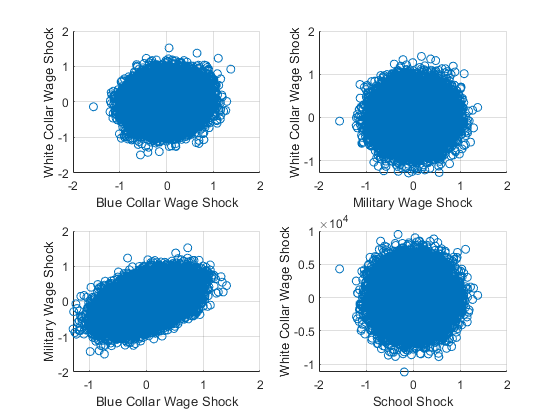

% Generate Scores
rng(123);
N = 50000;
mt_kw97_eps = mvnrnd(ar_mu, mt_varcov, N);
% graph
figure();
% subfigure 1
subplot(2,2,1);
scatter(mt_kw97_eps(:,1), mt_kw97_eps(:,2));
ylabel('White Collar Wage Shock');
xlabel('Blue Collar Wage Shock')
grid on;
% subfigure 2
subplot(2,2,2);
scatter(mt_kw97_eps(:,1), mt_kw97_eps(:,3));
ylabel('White Collar Wage Shock');
xlabel('Military Wage Shock')
grid on;
% subfigure 3
subplot(2,2,3);
scatter(mt_kw97_eps(:,3), mt_kw97_eps(:,2));
ylabel('Military Wage Shock');
xlabel('Blue Collar Wage Shock')
grid on;
% subfigure 4
subplot(2,2,4);
scatter(mt_kw97_eps(:,1), mt_kw97_eps(:,4));
ylabel('White Collar Wage Shock');
xlabel('School Shock')
grid on;

What are the covariance and correlation statistics?

disp([num2str(round(corrcoef(mt_kw97_eps),3))]);

     1       0.119       0.016       0.002      -0.003
 0.119           1       0.468      -0.003       0.004
 0.016       0.468           1      -0.003       0.001
 0.002      -0.003      -0.003           1      -0.005
-0.003       0.004       0.001      -0.005           1


disp([num2str(round(corrcoef(mt_kw97_eps),2))]);

   1        0.12        0.02           0           0
0.12           1        0.47           0           0
0.02        0.47           1           0           0
   0           0           0           1       -0.01
   0           0           0       -0.01           1


## Draw Five Correlated Shocks Using Cholesky Decomposition

Following what we did for bivariate normal distribution, we can now do the same for five different shocks at the same time (For more details see [Train (2009)](https://eml.berkeley.edu/~train/distant.html)):

- Draw 5 normal random variables that are uncorrelated

- Generate 5 correlated shocks

Draw the shocks

% Draws uniform and invert to standard normal draws
rng(123);
ar_unif_draws = rand(1,N*5);
ar_normal_draws = norminv(ar_unif_draws);
ar_draws_eta_1 = ar_normal_draws((N*0+1):N*1);
ar_draws_eta_2 = ar_normal_draws((N*1+1):N*2);
ar_draws_eta_3 = ar_normal_draws((N*2+1):N*3);
ar_draws_eta_4 = ar_normal_draws((N*3+1):N*4);
ar_draws_eta_5 = ar_normal_draws((N*4+1):N*5);

% Choesley decompose the variance covariance matrix
mt_varcov_chol = chol(mt_varcov, 'lower');

% Generate correlated random normals
mt_kp97_eps_chol = ar_mu' + mt_varcov_chol*([...
    ar_draws_eta_1; ar_draws_eta_2; ar_draws_eta_3; ar_draws_eta_4; ar_draws_eta_5]);
mt_kp97_eps_chol = mt_kp97_eps_chol';

Graph:

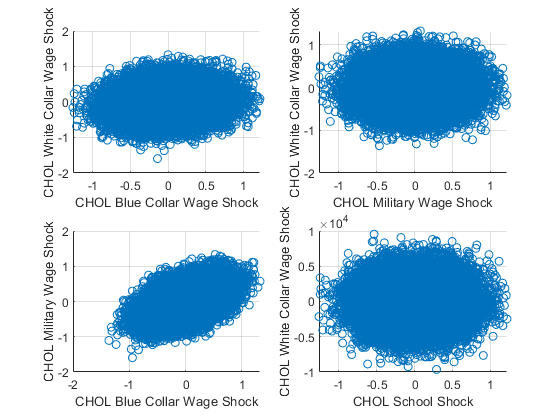

% graph
figure();
% subfigure 1
subplot(2,2,1);
scatter(mt_kp97_eps_chol(:,1), mt_kp97_eps_chol(:,2));
ylabel('CHOL White Collar Wage Shock');
xlabel('CHOL Blue Collar Wage Shock')
grid on;
% subfigure 2
subplot(2,2,2);
scatter(mt_kp97_eps_chol(:,1), mt_kp97_eps_chol(:,3));
ylabel('CHOL White Collar Wage Shock');
xlabel('CHOL Military Wage Shock')
grid on;
% subfigure 3
subplot(2,2,3);
scatter(mt_kp97_eps_chol(:,3), mt_kp97_eps_chol(:,2));
ylabel('CHOL Military Wage Shock');
xlabel('CHOL Blue Collar Wage Shock')
grid on;
% subfigure 4
subplot(2,2,4);
scatter(mt_kp97_eps_chol(:,1), mt_kp97_eps_chol(:,4));
ylabel('CHOL White Collar Wage Shock');
xlabel('CHOL School Shock')
grid on;

What are the covariance and correlation statistics?

disp([num2str(round(corrcoef(mt_kp97_eps_chol),3))]);

     1       0.119       0.021       0.008      -0.003
 0.119           1       0.479       0.008      -0.003
 0.021       0.479           1       0.002           0
 0.008       0.008       0.002           1      -0.004
-0.003      -0.003           0      -0.004           1


disp([num2str(round(corrcoef(mt_kp97_eps_chol),2))]);

   1        0.12        0.02        0.01           0
0.12           1        0.48        0.01           0
0.02        0.48           1           0           0
0.01        0.01           0           1           0
   0           0           0           0           1
